# Robotica Taller 2

*Daniel Esteban Ramirez Chiquillo*

*c.c. 1002479235*

*dramirezch@unal.edu.co*

## 1

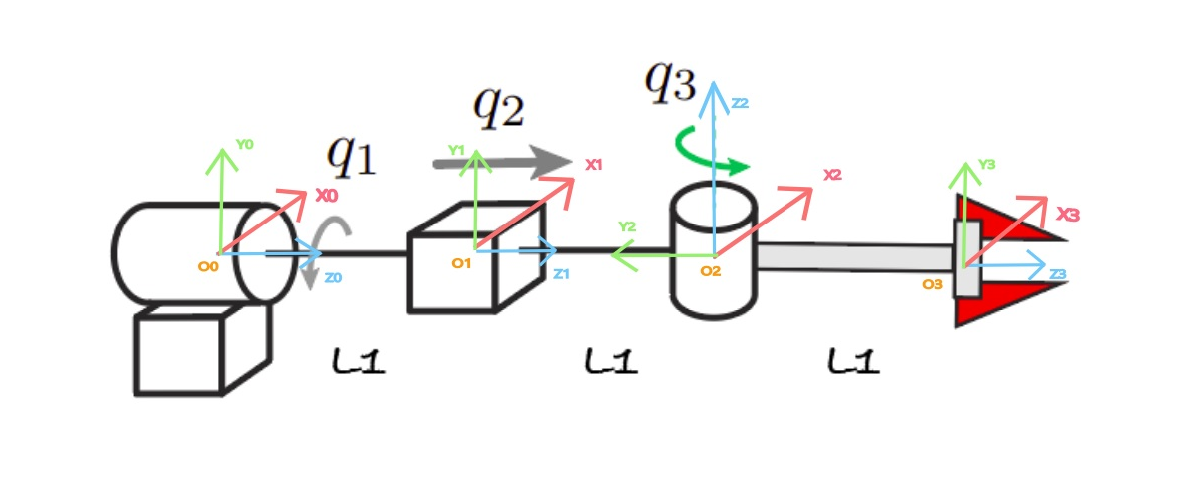

imshow("punto_1.jpg")

syms L1;
a = {0; 0; 0};
alpha = {0; 0; 90};
d = {0; L1; L1};
theta = {0; 0; 0};
table(a, alpha, d, theta)

ans = 3×4 table
      a      alpha       d       theta
    _____    ______    ______    _____

    {[0]}    {[ 0]}    {[ 0]}    {[0]}
    {[0]}    {[ 0]}    {[L1]}    {[0]}
    {[0]}    {[90]}    {[L1]}    {[0]}


## 2

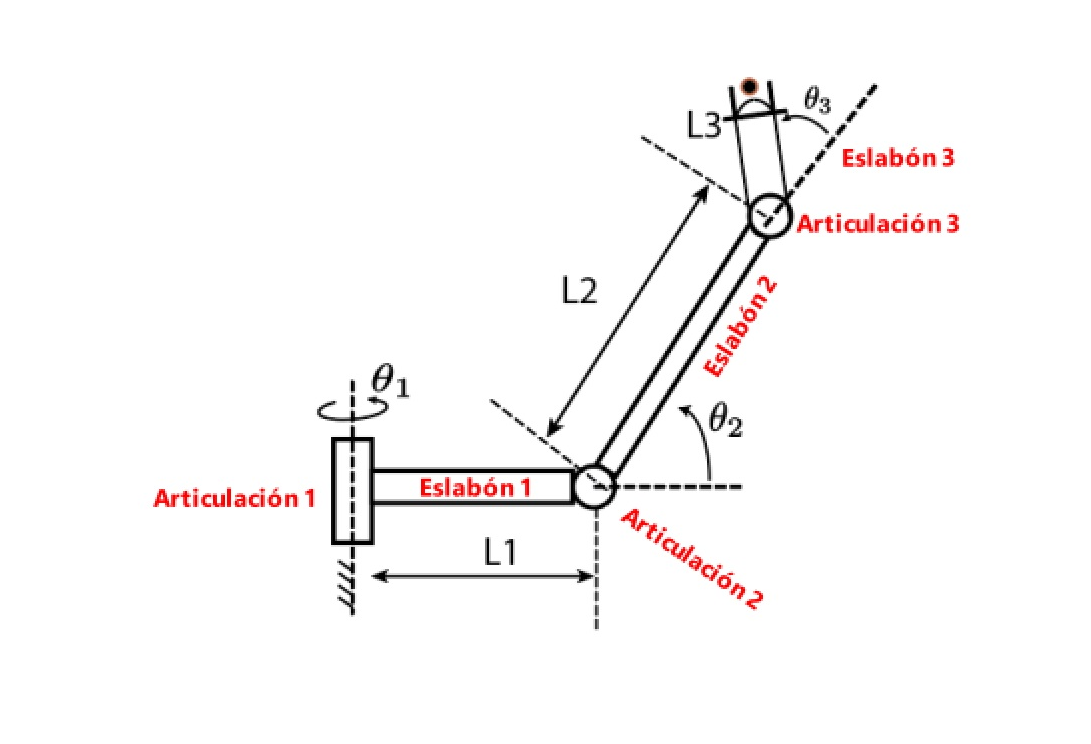

imshow("punto_2_a.jpg")

imshow("punto_2_b.jpg")
syms L1 L2 L3 theta_1 theta_2 theta_3;
a = {0; L1; L2; L3};
alpha = {0; 90; 0; 0};
d = {0; 0; 0; 0};
theta = {0; theta_1; theta_2; theta_3};
tabla_2 = table(a, alpha, d, theta)

tabla_2 = 4×4 table
      a       alpha       d         theta   
    ______    ______    _____    ___________

    {[ 0]}    {[ 0]}    {[0]}    {[      0]}
    {[L1]}    {[90]}    {[0]}    {[theta_1]}
    {[L2]}    {[ 0]}    {[0]}    {[theta_2]}
    {[L3]}    {[ 0]}    {[0]}    {[theta_3]}


t10 = mth_dh(L1, 90, 0, 0)

$$t10 = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{1}\\ 0 & 0 & -1 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

t21 = mth_dh(L2, 0, 0, theta_2)

$$t21 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{2}}{180}\right) & -\sin\left(\frac{\pi \,\theta_{2}}{180}\right) & 0 & L_{2}\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right)\\ \sin\left(\frac{\pi \,\theta_{2}}{180}\right) & \cos\left(\frac{\pi \,\theta_{2}}{180}\right) & 0 & L_{2}\,\sin\left(\frac{\pi \,\theta_{2}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

t32 = mth_dh(L3, 0, 0, theta_3)

$$t32 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{3}}{180}\right) & -\sin\left(\frac{\pi \,\theta_{3}}{180}\right) & 0 & L_{3}\,\cos\left(\frac{\pi \,\theta_{3}}{180}\right)\\ \sin\left(\frac{\pi \,\theta_{3}}{180}\right) & \cos\left(\frac{\pi \,\theta_{3}}{180}\right) & 0 & L_{3}\,\sin\left(\frac{\pi \,\theta_{3}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

t30 = t10*t21*t32

$$t30 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}\,\sigma_{4}-\sigma_{5}\,\sigma_{2} & 0 & L_{1}+L_{2}\,\sigma_{3}+L_{3}\,\sigma_{3}\,\sigma_{5}-L_{3}\,\sigma_{2}\,\sigma_{4}\\ 0 & 0 & -1 & 0\\ \sigma_{3}\,\sigma_{4}+\sigma_{5}\,\sigma_{2} & \sigma_{1} & 0 & L_{2}\,\sigma_{2}+L_{3}\,\sigma_{3}\,\sigma_{4}+L_{3}\,\sigma_{5}\,\sigma_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{3}\,\sigma_{5}-\sigma_{2}\,\sigma_{4}\\ \sigma_{2}=\sin\left(\frac{\pi \,\theta_{2}}{180}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,\theta_{2}}{180}\right)\\ \sigma_{4}=\sin\left(\frac{\pi \,\theta_{3}}{180}\right)\\ \sigma_{5}=\cos\left(\frac{\pi \,\theta_{3}}{180}\right) \end{array}$$

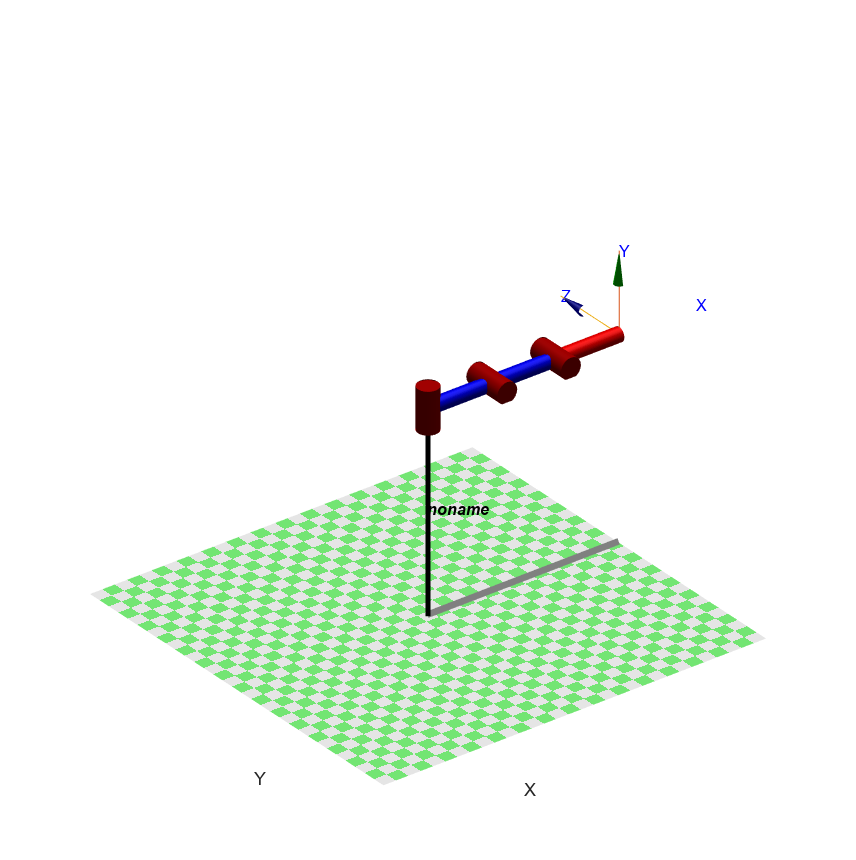

Theta_1=0;
Theta_2=0;
Theta_3=0;



L1 = Link('revolute','a',1,'alpha',pi/2,'d',0,'offset',Theta_1);
L2 = Link('revolute','a',1,'alpha',0,'d',0,'offset',Theta_2);
L3 = Link('revolute','a',1,'alpha',0,'d',0,'offset',Theta_2);

Robot = SerialLink([L1 L2 L3]);
 

q_z = [0 0 0];
q_1 = [pi/4 pi/6 pi/3];

Robot.plot(q_z)

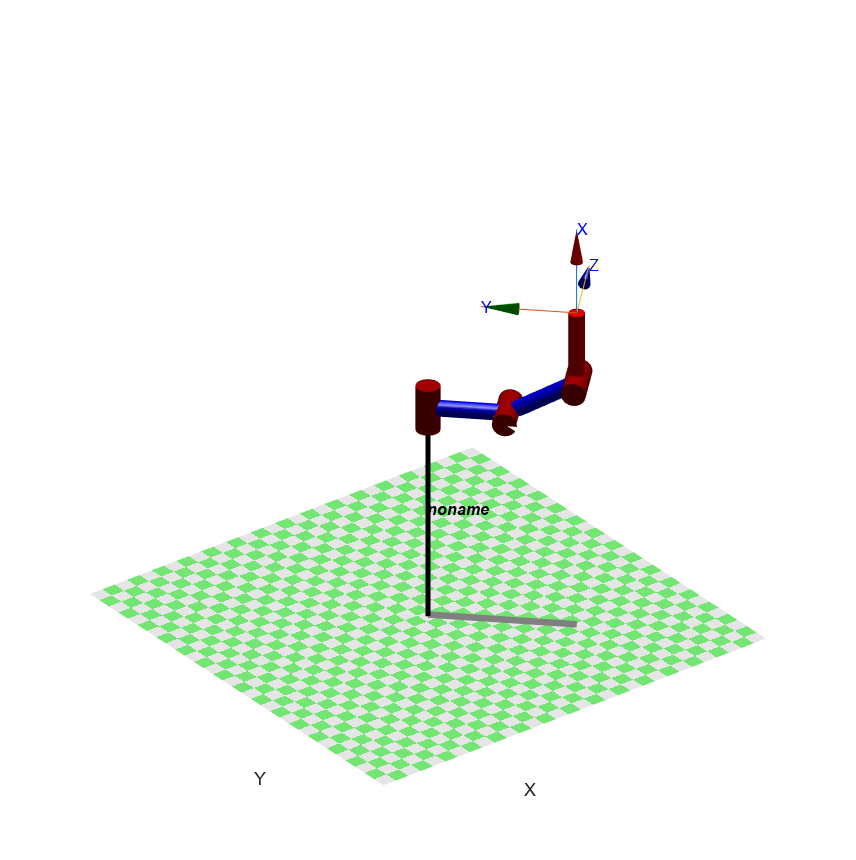

Robot.plot(q_1)

## 3

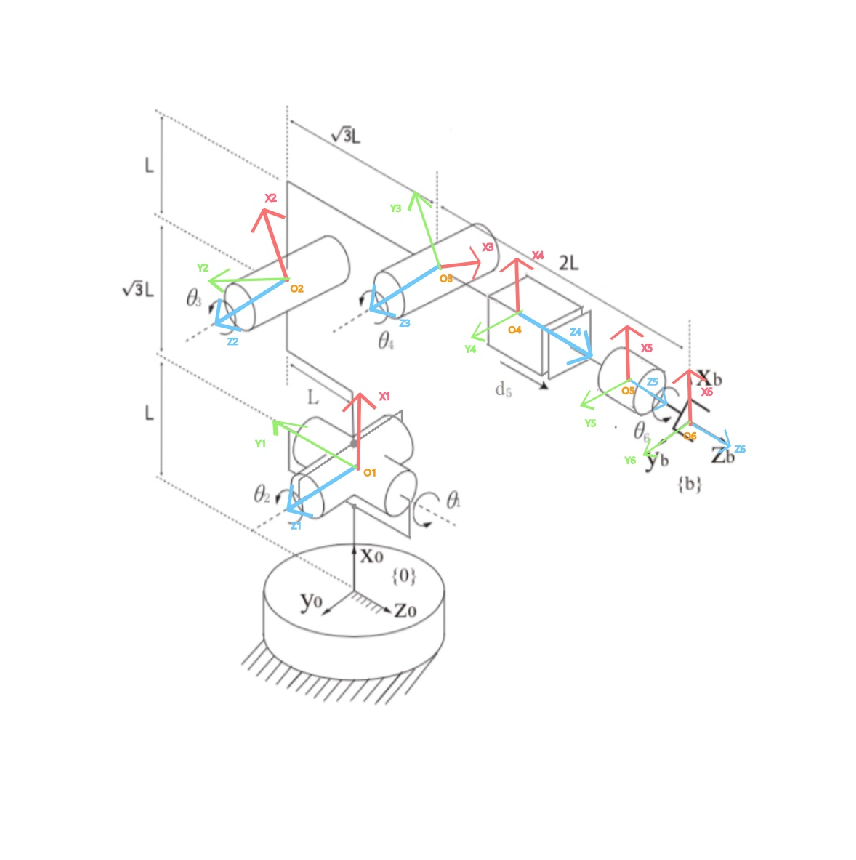

imshow("punto_3.jpg")

syms L theta_1 theta_2 theta_3 theta_4  ds theta_6;
a = {L; sqrt(L^2 + (sqrt(3)*L)^2); sqrt(L^2 + (sqrt(3)*L)^2); 0; 0; 0};
alpha = {-90; 0; 0; 90; 0; 0};
d = {0; 0; 0; 2*L; ds; 0};
theta = {theta_1; theta_2; theta_3; theta_4; 0; theta_6};
tabla_3 = table(a, alpha, d, theta) 

tabla_3 = 6×4 table
            a             alpha        d          theta   
    _________________    _______    _______    ___________

    {[L            ]}    {[-90]}    {[  0]}    {[theta_1]}
    {[2*(L^2)^(1/2)]}    {[  0]}    {[  0]}    {[theta_2]}
    {[2*(L^2)^(1/2)]}    {[  0]}    {[  0]}    {[theta_3]}
    {[            0]}    {[ 90]}    {[2*L]}    {[theta_4]}
    {[            0]}    {[  0]}    {[ds ]}    {[      0]}
    {[            0]}    {[  0]}    {[  0]}    {[theta_6]}


t10 = mth_dh(L, -90, 0, theta_1)

$$t10 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{1}}{180}\right) & 0 & -\sin\left(\frac{\pi \,\theta_{1}}{180}\right) & L\,\cos\left(\frac{\pi \,\theta_{1}}{180}\right)\\ \sin\left(\frac{\pi \,\theta_{1}}{180}\right) & 0 & \cos\left(\frac{\pi \,\theta_{1}}{180}\right) & L\,\sin\left(\frac{\pi \,\theta_{1}}{180}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

t21 = mth_dh(sqrt(L^2 + (sqrt(3)*L)^2), 0, 0, theta_2)

$$t21 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{2}}{180}\right) & -\sin\left(\frac{\pi \,\theta_{2}}{180}\right) & 0 & 2\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right)\,\sqrt{L^{2}}\\ \sin\left(\frac{\pi \,\theta_{2}}{180}\right) & \cos\left(\frac{\pi \,\theta_{2}}{180}\right) & 0 & 2\,\sin\left(\frac{\pi \,\theta_{2}}{180}\right)\,\sqrt{L^{2}}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

t32 = mth_dh(sqrt(L^2 + (sqrt(3)*L)^2), 0, 0, -theta_3)

$$t32 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{3}}{180}\right) & \sin\left(\frac{\pi \,\theta_{3}}{180}\right) & 0 & 2\,\cos\left(\frac{\pi \,\theta_{3}}{180}\right)\,\sqrt{L^{2}}\\ -\sin\left(\frac{\pi \,\theta_{3}}{180}\right) & \cos\left(\frac{\pi \,\theta_{3}}{180}\right) & 0 & -2\,\sin\left(\frac{\pi \,\theta_{3}}{180}\right)\,\sqrt{L^{2}}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

t43 = mth_dh(0, 90, 2*L, theta_4)

$$t43 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{4}}{180}\right) & 0 & \sin\left(\frac{\pi \,\theta_{4}}{180}\right) & 0\\ \sin\left(\frac{\pi \,\theta_{4}}{180}\right) & 0 & -\cos\left(\frac{\pi \,\theta_{4}}{180}\right) & 0\\ 0 & 1 & 0 & 2\,L\\ 0 & 0 & 0 & 1 \end{array}\right)$$

t54 = mth_dh(0, 0, ds, 0)

$$t54 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \mathrm{ds}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

t65 = mth_dh(0, 0, 0, theta_6)

$$t65 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{6}}{180}\right) & -\sin\left(\frac{\pi \,\theta_{6}}{180}\right) & 0 & 0\\ \sin\left(\frac{\pi \,\theta_{6}}{180}\right) & \cos\left(\frac{\pi \,\theta_{6}}{180}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### MTH TCP

syms l_tool
t_tcp = mth_dh(0, 0, l_tool, 0)

$$t\_tcp = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{\mathrm{tool}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Modelo geométrico directo

t10 = mth_dh(L, -90, 0, 0);
t21 = mth_dh(sqrt(L^2 + (sqrt(3)*L)^2), 0, 0, 0);
t32 = mth_dh(sqrt(L^2 + (sqrt(3)*L)^2), 0, 0, 0);
t43 = mth_dh(0, 90, 2*L, 0);
t54 = mth_dh(0, 0, 0, 0);
t65 = mth_dh(0, 0, 0, 0);
t_mgd = t10*t21*t32*t43*t54*t65

$$t\_mgd = \left(\begin{array}{cccc} 1 & 0 & 0 & L+4\,\sqrt{L^{2}}\\ 0 & 1 & 0 & 2\,L\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Posición y orientación con configuración dada

t10 = mth_dh(1, -90, 0, 60);
t21 = mth_dh(sqrt(1^2 + (sqrt(3)*1)^2), 0, 0, -45);
t32 = mth_dh(sqrt(1^2 + (sqrt(3)*1)^2), 0, 0, -90);
t43 = mth_dh(0, 90, 2*1, 45);
t54 = mth_dh(0, 0, 1.5, 0);
t65 = mth_dh(0, 0, 0, 30);
t_mgd_conf = t10*t21*t32*t43*t54*t65

t_mgd_conf =    -0.4330   -0.7500   -0.5000   -1.9821
    0.2500    0.4330   -0.8660    0.5670
    0.8660   -0.5000         0    2.8284
         0         0         0    1.0000


## Funciones de ayuda

function [MTHtx] = mth_trans_x(dist)
    MTHtx = [1 0 0 dist; 0 1 0 0; 0 0 1 0; 0 0 0 1];
end

function [MTHty] = mth_trans_y(dist)
    MTHty = [1 0 0 0; 0 1 0 dist; 0 0 1 0; 0 0 0 1];
end

function [MTHtz] = mth_trans_z(dist)
    MTHtz = [1 0 0 0; 0 1 0 0; 0 0 1 dist; 0 0 0 1];
end

function [MTHrx] = mth_rot_x(ang)
    MTHrx = [1 0 0 0; 0 cosd(ang) -sind(ang) 0; 0 sind(ang) cosd(ang) 0; 0 0 0 1];
end

function [MTHry] = mth_rot_y(ang)
    MTHry = [cosd(ang) 0 sind(ang) 0; 0 1 0 0; -sind(ang) 0 cosd(ang) 0; 0 0 0 1];
end

function [MTHrz] = mth_rot_z(ang)
    MTHrz = [cosd(ang) -sind(ang) 0 0; sind(ang) cosd(ang) 0 0; 0 0 1 0; 0 0 0 1];
end

function [MTHt] = mth_trans(x,y,z)
    MTHt = mth_trans_x(x) * mth_trans_y(y) * mth_trans_z(z);
end

function [MTHr] = mth_rot(x,y,z)
    MTHr = mth_rot_x(x) * mth_rot_y(y) * mth_rot_z(z);
end

function [MTH] = mth(x,y,z, angx, angy, angz)
    MTH = mth_trans(x,y,z) * mth_rot(angx,angy,angz);
end

function [MTH_inv] = mth_inv(mth)
    R = mth(1:3, 1:3);
    d = mth(1:3, 4);
    MTH_inv = [R' -R'*d; 0 0 0 1];
end

function [MTH_DH] = mth_dh(a_i, alpha_i, d_i, theta_i)
    MTH_DH = mth_rot_z(theta_i) * mth_trans_z(d_i) * mth_trans_x(a_i) * mth_rot_x(alpha_i);
end
